# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 11 REPORT**

**JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

VLFeat configuration:

VLFEAT_DIR = '/Users/jnalexander/Projects/VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));

a) 

First, train the model with a subset of categories:

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 600
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 2.25 s
kmeans: Elkan iter 0: energy = 8.30625e+09, dist. calc. = 38607477
kmeans: Elkan iter 1: energy <= 5.70836e+09, dist. calc. = 8249339
kmeans: Elkan iter 2: energy <= 5.50007e+09, dist. calc. = 7274123
kmeans: Elkan iter 3: energy <= 5.41153e+09, dist. calc. = 6029357
kmeans: Elkan iter 4: energy <= 5.36473e+09, dist. calc. = 4741069
kmeans: Elkan iter 5: energy <= 5.33439e+09, dist. calc. = 3674918
kmeans: Elkan iter 6: energy <= 5.31124e+09, dist. calc. = 3090821
kmeans: Elkan iter 7: energy <= 5.29413e+09, dist. calc. = 2715649
kmeans: Elkan iter 8: energy <= 5.28015e+09, dis

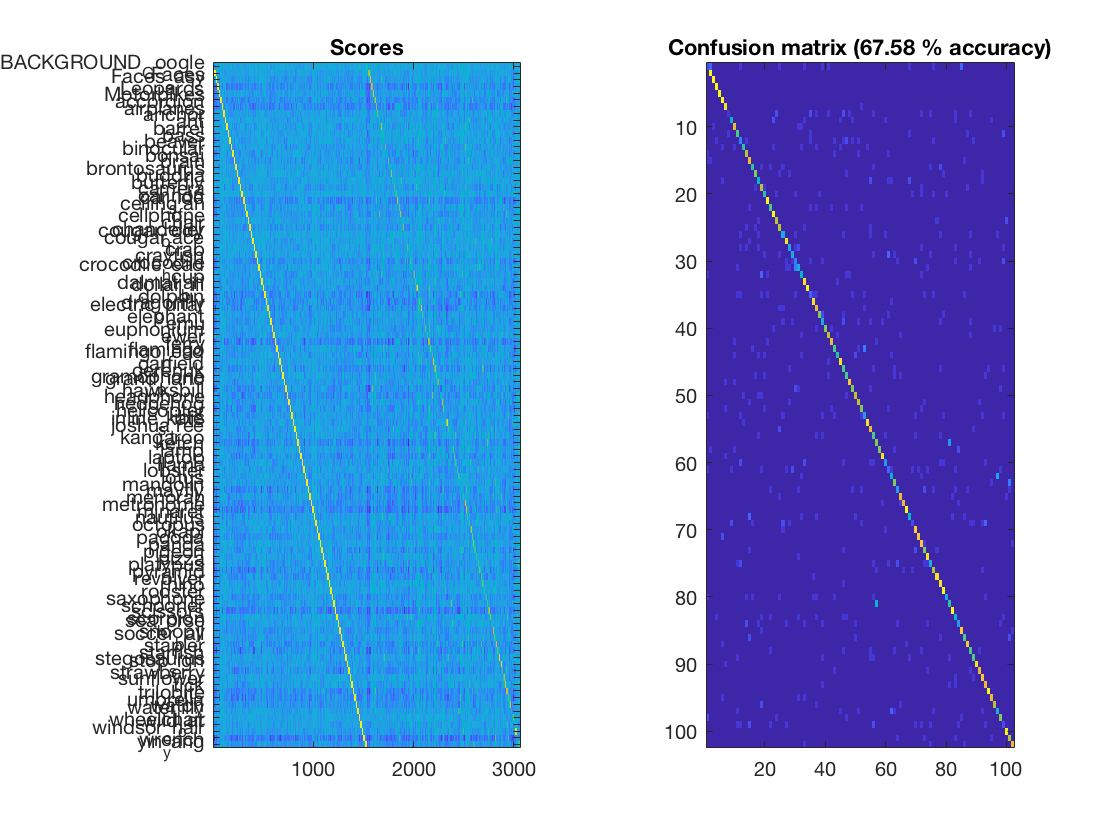

run('phow_caltech101.m');

Add a function to train visualize the images in a green framework if the classification is correct and in a red framework if it does not:

modelPath = 'data/tiny-model.mat';
imageDir = 'data/caltech-101/101_ObjectCategories/Leopards/';
imageNames = dir(fullfile(imageDir, '*.jpg'));
imagePaths = {};
imgPathIdx=1;
for imIdx=40:49    
    imagePaths{imgPathIdx} = fullfile(imageDir, imageNames(imIdx).name);
    imgPathIdx = imgPathIdx + 1;
end

Index exceeds matrix dimensions.

visualizeImgClass(imagePaths, modelPath);

b) 

*What are the PHOW descriptors?  *

They represent the Pyramid Histogram Of visual Words. 

The function to obtain them is 

%[FRAMES, DESCRS] = vl_phow(IMG)

DESCRS, Each column of DESCRS is the descriptor of the corresponding frame in FRAMES. A descriptor is a 128-dimensional vector of class UINT8.

It represents a 4x4 spatial histogram of gradient orientations, each with 8 different directions, leading to a 4x4x8=128 dimensional vector.

FRAMES(1:2,:) are the x,y coordinates of the center of each descriptor, FRAMES(3,:) is the contrast of the descriptor, as returned by VL_DSIFT() (for colour variant, contranst is computed on the intensity channel). FRAMES(4,:) is the size of the bin of the descriptor.

*What does the Sizes parameter mean? *

It's the scales at which the dense SIFT features are extracted. Each value is used as the spatial bin size in pixels when extracting a dense set of SIFT features from the image.

*What does happen if the Sizes parameter is augmented? *

From the lectures, the code to calculate the phow descriptors:

% step = 5;
% for size=[5,7,10,12]
%     [x,y]=meshgrid(1:step:width, 1:step:height);
%     frames = [x(:)'; y(:)'];
%     frames(3,:) = size/3;
%     frames(4,:) = 0;
%     [frames, descrs] = vl_sift(im, 'Frames', frames);
% end

It can be observed that if the size is increased the size of the bin of the descriptor is increased.				

*What does the Step parameter mean?* 

Step (in pixels) of the grid at which the dense SIFT features are extracted.

*What does happen if the Step parameter is augmented?*